close all
clear all

% this script reconstructs the spatial information from the raw signal
% change this file path as needed; any of the file names below will work

% "your_path" ...\config_A_007
% "your_path" ...\config_A_008
% "your_path" ...\config_A_009
% "your_path" ...\config_A_010
% "your_path" ...\config_B_009
% "your_path" ...\config_B_010
% "your_path" ...\config_B_011
% "your_path" ...\config_B_012

filename = 'config_B_011'

filename = 'config_B_011'

full_path = strcat('C:\Users\Mog\Desktop\', filename, '.mat')

full_path = 'C:\Users\Mog\Desktop\config_B_011.mat'

%%% INITIAL PARAMETERS

full_data = load(full_path);
full_mag = full_data.final_magnetisation;
full_I_list = full_data.I_list;
N_fourier = 49;
N_loops = 3;
N_effective_loops = N_loops*2;
FOV = 5.0e-3;
delta_k = 1/FOV;


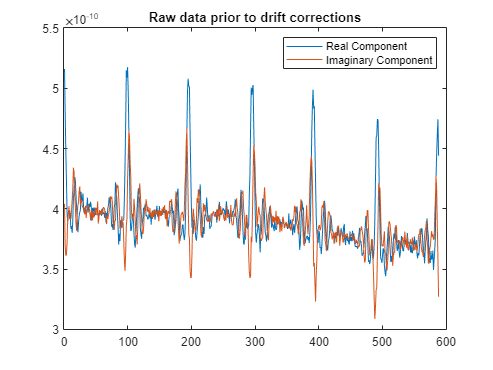

%%% DRIFT CORRECTIONS

full_mag_seq=reshape(full_mag,(N_fourier*N_loops*4),1);

real_raw_mag = real(full_mag_seq);
imag_raw_mag = imag(full_mag_seq);

plot(real_raw_mag);
hold on;
plot(imag_raw_mag);
title('Raw data prior to drift corrections');
legend('Real Component', 'Imaginary Component');
hold off;

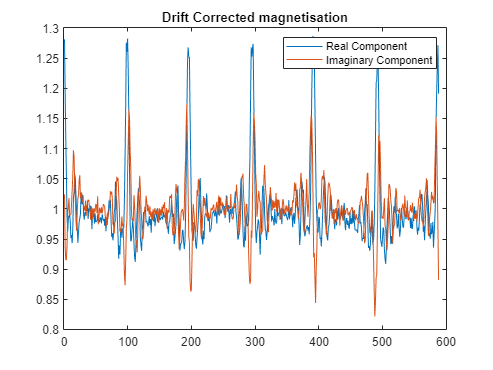


%drift correction (REAL part)
x=1:length(real_raw_mag);
[a b]=polyfit(x,real_raw_mag,3);
fitmag=a(4)+a(3)*x+a(2)*x.^2+a(1)*x.^3;
real_mag=(real_raw_mag./(fitmag)');

%drift correction (IMAGINARY part)
x=1:length(imag_raw_mag);
[a b]=polyfit(x,imag_raw_mag,3);
fitmag=a(4)+a(3)*x+a(2)*x.^2+a(1)*x.^3;
imag_mag=(imag_raw_mag./(fitmag)');

plot(real_mag);
hold on;
plot(imag_mag);
title('Drift Corrected magnetisation');
legend('Real Component', 'Imaginary Component');
hold off;

% RE-ARRANGES THE DATA INTO INDIVIDUAL RUNS i.e. (-K_max -> +K_max)

I_list = full_I_list(1:25); %takes the first ramp
full_mag=reshape( (real_mag + imag_mag*sqrt(-1)) , 4*N_fourier, N_loops);

if FOV==(2.5e-3);
    %for FOV=2.5mm
    segment1 = full_mag(1:25, :);
    segment2 = full_mag(26:50, :);
    segment3 = full_mag(51:75, :);
    segment4 = full_mag(76:100, :);


elseif FOV==(5.0e-3);
    %for FOV=5.0mm
    segment1 = full_mag(1:49, :);
    segment2 = full_mag(50:98, :); 
    segment3 = full_mag(99:147, :);
    segment4 = full_mag(148:196, :);

    else
        disp('error, wrong FOV set');
end

LHS = [segment2, flipud(segment1)];
RHS = [segment4, flipud(segment3)];

reformatted_combined_mag = [LHS(1:end-1, :).', flipud(RHS).']';

% figure();
% for i=1:(N_loops*2);
%     plot(real(reformatted_combined_mag(:,i)));
%     plot(imag(reformatted_combined_mag(:,i)));
%     title('Drift corrected and combined M(k)');
%     hold on;
% end;
% hold off;


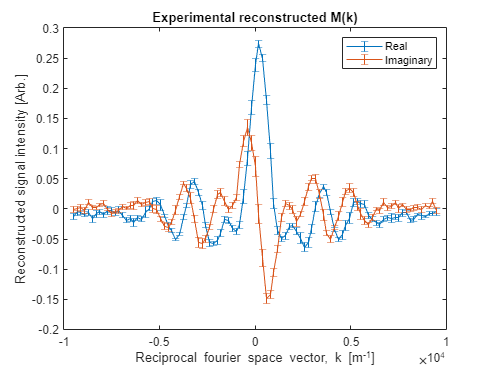

%Error analysis of magnetisation of signal (REAL part)
mean_real = mean(real(reformatted_combined_mag), 2);
stdev_mag_real = std(real(reformatted_combined_mag)');
mag_error_real = stdev_mag_real / sqrt(N_effective_loops);

%Error analysis magnetisation of signal (IMAGINARY part)
mean_imag = mean(imag(reformatted_combined_mag), 2);
stdev_mag_imag = std(imag(reformatted_combined_mag)');
mag_error_imag = stdev_mag_imag / sqrt(N_effective_loops);

mean_real = mean_real - mean(mean_real); %removes mean of signal (real part)
mean_imag = mean_imag - mean(mean_imag); %removes mean of signal (imag part)

k_list = linspace(-((length(mean_real)/2)-1)*delta_k, ((length(mean_real)/2)-1)*delta_k, length(mean_real));

errorbar(k_list, mean_real, mag_error_real);
hold on;
errorbar(k_list, mean_imag, mag_error_imag);
title('Experimental reconstructed M(k)');
xlabel('Reciprocal fourier space vector, k [m^{-1}]');
ylabel('Reconstructed signal intensity [Arb.]');
legend('Real', 'Imaginary');
hold off;

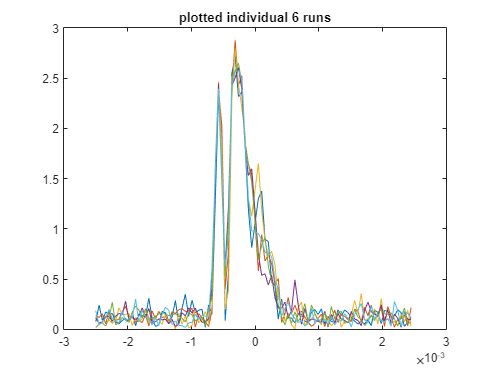

%%% DATA PROCESSING OF SPATIAL DOMAIN (RECONSTRUCTIONS)

x_axis = linspace(-FOV/2, FOV/2, 97);
x_axis(49) = []; %removes x=0 since our 0th frequency component has been removed
x_axis(end) = []; %removes x=x_max since M(k) last point removed
reformatted_combined_mag(end, :) = []; %counteracting windowing effects via DFT periodicity

spatial_reformatted = fftshift(fft(reformatted_combined_mag), 1); %performs Fourier-Transform
spatial_reformatted(49, :) = []; %removes 0th freq pointt
spatial_reformatted = abs(spatial_reformatted);
spatial_reformatted = fliplr(spatial_reformatted); %flips distribution

%plot each individual distributions
plot(x_axis, spatial_reformatted(:,1));
hold on;
plot(x_axis, spatial_reformatted(:,2));
plot(x_axis, spatial_reformatted(:,3));
plot(x_axis, spatial_reformatted(:,4));
plot(x_axis, spatial_reformatted(:,5));
plot(x_axis, spatial_reformatted(:,6));
title('plotted individual 6 runs')
hold off;

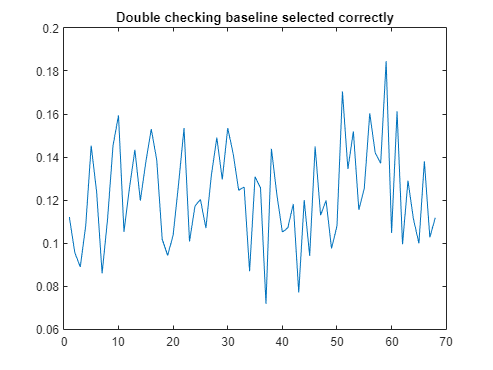

%%% ERROR ANALYSIS OF THE SPATIAL DOMAIN
% uses a baseline correction to center mean intensity to 0 
% spatial_reformatted -> contains M(k) with size 6(runs) x 95(fourier points)

mean_fft_data = mean(spatial_reformatted', 1);

% ensure these are set correctly (selects baseline to reduce noise)
baseline_i1 = 35;
baseline_i2 = 63;
baseline = [ mean_fft_data(1:baseline_i1) , mean_fft_data(baseline_i2:end) ];
plot(baseline) %double checking correct baseline measurement selected
title('Double checking baseline selected correctly');

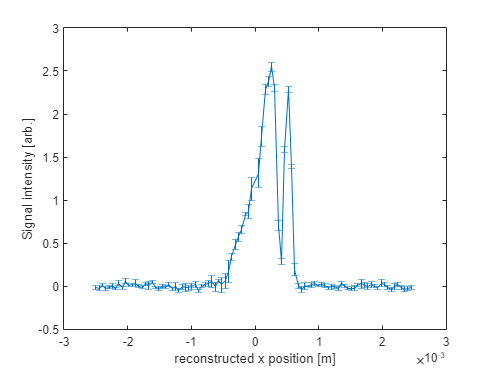


mean_fft_data = mean_fft_data - mean(baseline); %baseline removed

maximum_amp = max(mean_fft_data); %factor for normalisation

%mean_fft_data = mean_fft_data ./ maximum_amp %renormalised 

%error analysis for spatial information
std_fft_data = std(spatial_reformatted');
error_fft_data = std_fft_data ./ sqrt(N_loops*2);
%error_fft_data = error_fft_data ./ maximum_amp

errorbar(x_axis, fliplr(mean_fft_data), error_fft_data);
xlabel('reconstructed x position [m]')
ylabel('Signal intensity [arb.]')


output_name = strcat(filename, '.txt');
output = [ x_axis', fliplr(mean_fft_data)' ];
writematrix(output, output_name);
% error_plot_filename = strcat('Spatial_(error)', '_',  filename, '.fig')
% savefig( error_plot , error_plot_filename )